
8793

ans = 8793

   75            2280           26.39           26.66        3
IAE = 26.4995				P = 24.2797		I = 71.175		D = 0.77496
IAE = 27.3944				P = 29.042		I = 63.6373		D = 0.63229
IAE = 26.4024				P = 24.6141		I = 72.8757		D = 0.60633
IAE = 26.3971				P = 24.4173		I = 72.6856		D = 0.60794
IAE = 26.424				P = 23.5263		I = 73.2889		D = 0.6081
IAE = 26.4101				P = 24.6112		I = 72.6139		D = 0.63078
IAE = 26.4027				P = 24.7259		I = 72.6289		D = 0.60948
IAE = 26.4215				P = 25.131		I = 72.9417		D = 0.60994
IAE = 26.397				P = 24.4771		I = 74.6987		D = 0.60786
IAE = 26.3949				P = 24.5741		I = 73.2118		D = 0.61018
IAE = 26.6932				P = 24.3857		I = 38.898		D = 0.60052
IAE = 26.3926				P = 24.6283		I = 72.395		D = 0.61056
IAE = 26.3919				P = 24.6144		I = 72.5873		D = 0.60999
IAE = 26.4426				P = 25.6793		I = 72.8825		D = 0.7411
IAE = 27.0591				P = 23.4288		I = 26.5473		D = 0.61074
IAE = 26.4573				P = 21.8764		I = 71.1918		D = 0.59624
IAE = 26.3919				P = 24.6061		I = 72.8583		D = 0.60951
IAE = 26.43

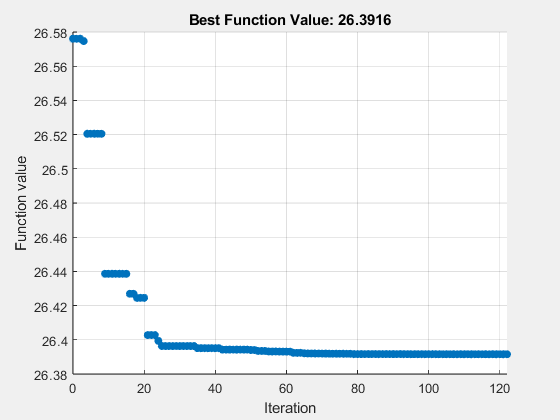

% Set nondefault solver options
options = optimoptions("particleswarm","InertiaRange",Inertia_range,...
    "SelfAdjustmentWeight",2.8,"SocialAdjustmentWeight",1.3,"MaxIterations",...
    600,"Display","iter","PlotFcn","pswplotbestf");

% Solve
[sol,obj] = particleswarm(@tunning,numvar,lower_bounds,...
    upper_bounds,options);


% Clear variables
clearvars options